Anant Mital 

Student # 272484

## Problem 6

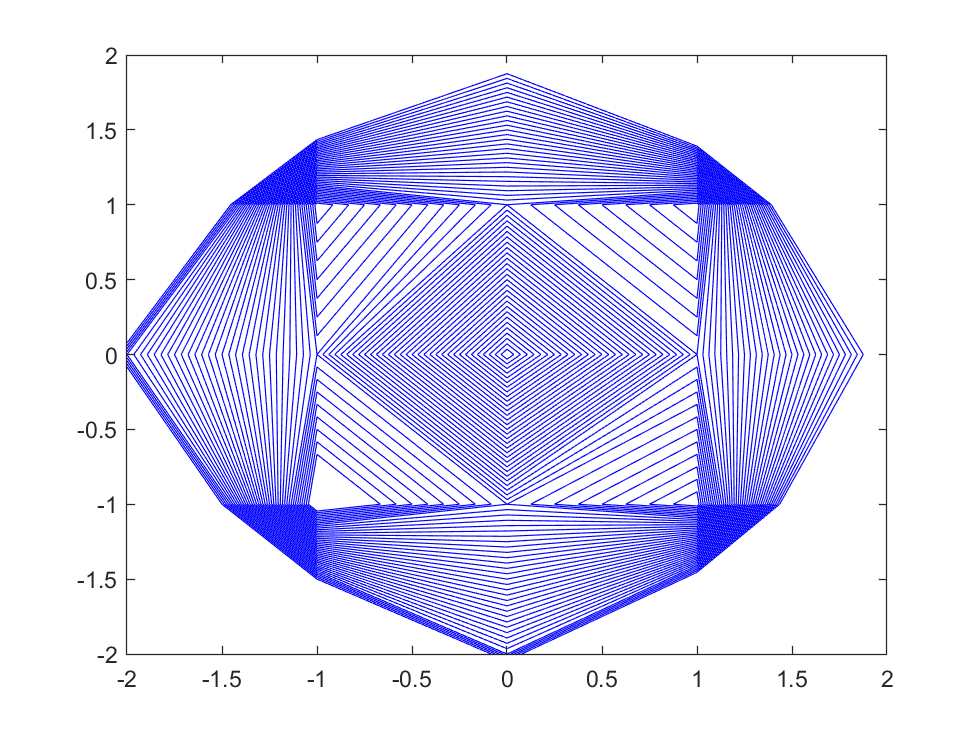

[X,Y] = meshgrid(-2:2);
pobj = VideoWriter('contour', 'mpeg-4');
open(pobj);
for m = 0.5:0.05:10
    Z = X + Y + 0.5*m*(X.^2 + Y.^2 - 2).^2;
    contour(X, Y, Z, 0:0.5:20, 'Color', 'b');
    frame = getframe;
    writeVideo(pobj, frame);
end

close(pobj);
